# Lab 7

Marc Eftimie, Raiyan Siddique, Sam Mendelson

## Experiment 1

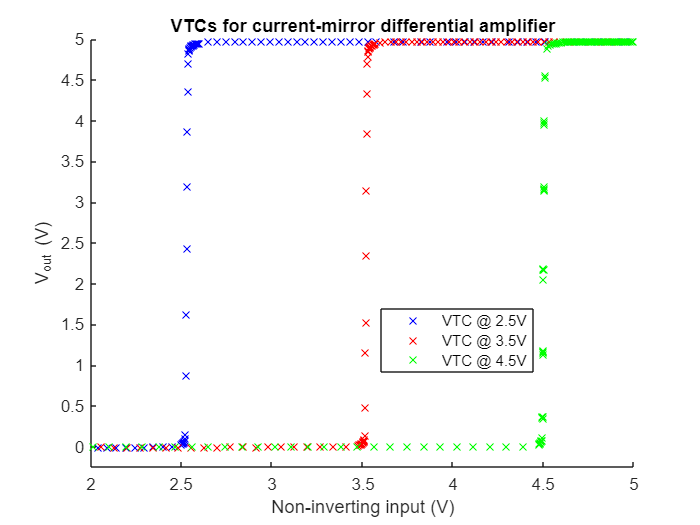

clear;
clf;
hold on;

load("Ex1_1_2-5.mat");
plot(Ch1, Vout, 'bx', 'DisplayName', 'VTC @ 2.5V');

load("Ex1_1_3-5.mat");
plot(Ch1, Vout, 'rx', 'DisplayName', 'VTC @ 3.5V');

load("Ex1_1_4-5.mat");
plot(Ch1, Vout, 'gx', 'DisplayName', 'VTC @ 4.5V');

legend("Position", [0.54385,0.29151,0.21843,0.12231]);
xlim([2 5]);
ylim([-0.25 5]);
title("VTCs for current-mirror differential amplifier")
xlabel("Non-inverting input (V)");
ylabel("V_{out} (V)");
hold off;

Compared to the VTCs from Lab 6, the amplifier now sits at 0V until we hit the non-inverting input value.

## Experiment 2

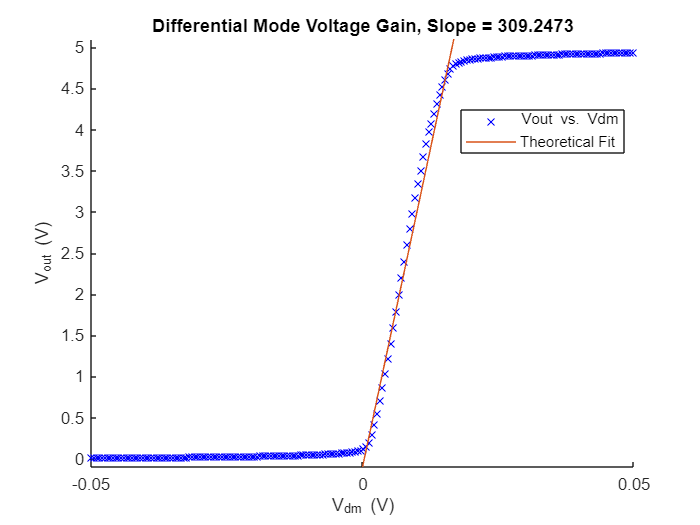

clear;
clf;

hold on;
load("Ex2_1_2-5.mat");
vspace = linspace(0, 0.018);
vfit = 309.2473*vspace - 0.1019;

plot(Vdm, Vout, "bx");
plot(vspace, vfit);

xlim([-0.05 0.05]);
ylim([-0.1 5.1]);
legend("V{out} vs. V{dm}", "Theoretical Fit", "location", "best");
title("Differential Mode Voltage Gain, Slope = 309.2473");
xlabel("V_{dm} (V)");
ylabel("V_{out} (V)");
hold off;

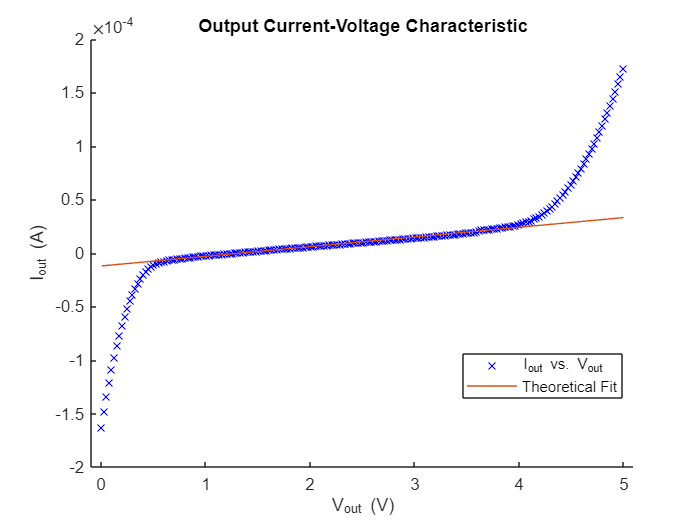

clear;
clf;

% Vdm = 0, measuring current flowing into output of amplifier
load("Ex2_2_2-5.mat");
vspace = linspace(0, 5);
vfit = 9.0331e-6*vspace - 1.2085e-5;

hold on;
plot(Vout, Iout, "bx");
plot(vspace, vfit);
%ylim([-0.05 0.05]);
xlim([-0.1 5.1]);
legend("I_{out} vs. V_{out}", "Theoretical Fit", "location", "best");
title("Output Current-Voltage Characteristic");
ylabel("I_{out} (A)");
xlabel("V_{out} (V)");

The slope of the best-fit line is 9.0331e-6 Ohms, so it's a very small incremental output resistance.

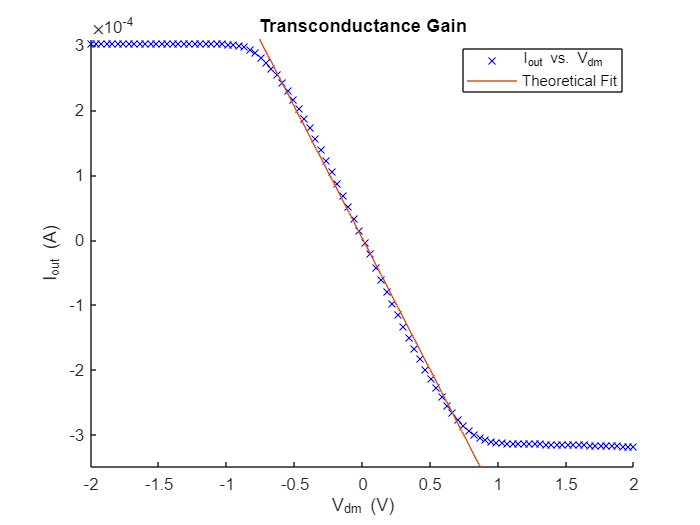

clear;
clf;
hold on;
load("Ex2_3_2-5.mat");

% Vout fixed at 2.2 - sweeping Vdm over a large range where Iout
% saturates both for positive and negative values of Vdm

vspace = linspace(-1, 1);
vfit = -4.0573e-4*vspace + 2.1045e-6;
plot(Vdm, Iout, "bx");
plot(vspace, vfit);

xlim([-2 2]);
ylim([-3.5e-4 3.1e-4]);
legend("I_{out} vs. V_{dm}", "Theoretical Fit", "location", "best");
title("Transconductance Gain");
xlabel("V_{dm} (V)");
ylabel("I_{out} (A)");
hold off;

Our transconductance gain (the slope of the line * -1) is 0.00040573S.